# Surface Plot Properties

This code sets up the intial surface plot.

x = 0:0.5:6;
y = 0:0.5:6;
[X, Y] = meshgrid(x, y);
Z = sin(X) + cos(Y);

## Task 1

You can access and modify surface plot properties by including an output variable to the `surf` function.

`s` `=` `surf``(``x``,``y``,``z``)`

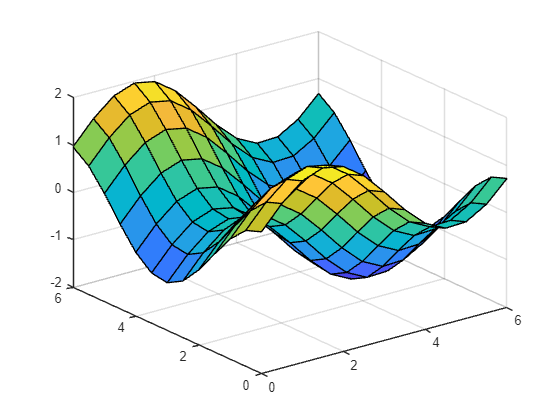

s =   Surface with properties:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [13×13 double]
           YData: [13×13 double]
           ZData: [13×13 double]
           CData: [13×13 double]

  Show all properties


s = surf(X, Y, Z)

## Task 2

The color of the lines between the patches is determined by the `EdgeColor` property.

`s.EdgeColor` `=` `"interp"`

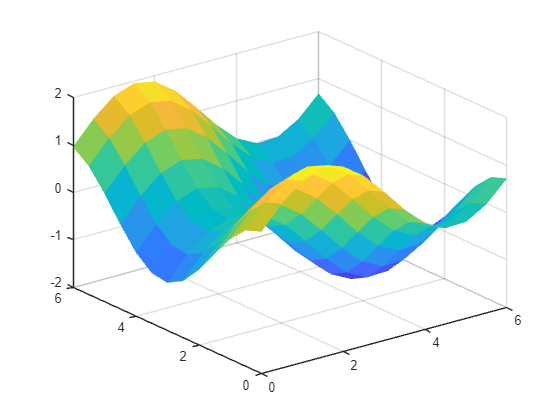

s.EdgeColor = "none";

## Task 3

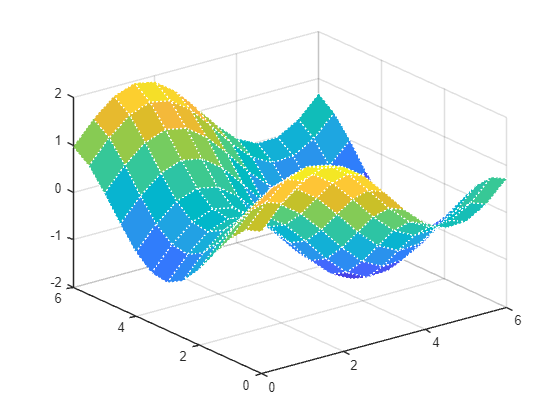

s.EdgeColor = "w";
s.LineStyle = ":";

## Task 4

The color of the patches themselves is determined by the `FaceColor` property. By default, it is set to `"flat"` which means that the whole face is a single color, determined by the `CData` value of the lower left vertex.

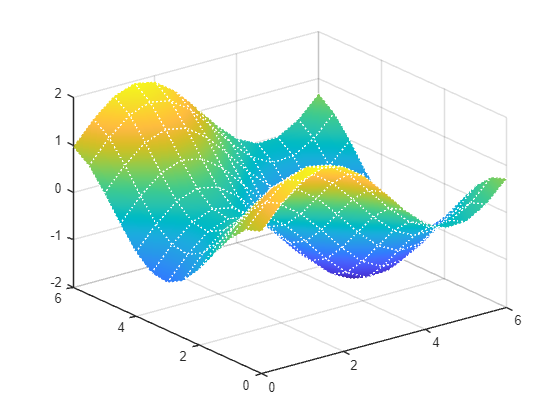

s.FaceColor = "interp";

## Task 5

By default, surfaces in MATLAB are colored according to the values of `Z`. This color information is stored in the `CData` property of the surface.

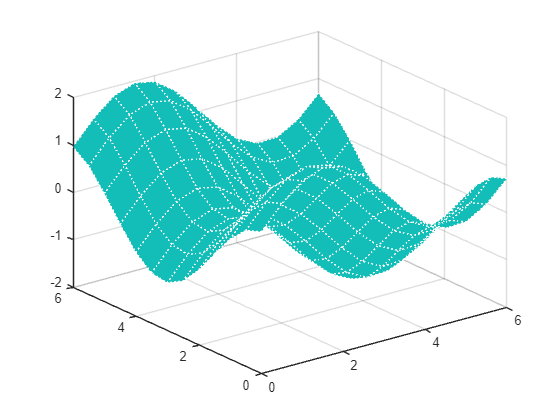

s.CData = zeros(size(Z));

## Task 6

Properties that contain `Alpha` control the transparency of the color.

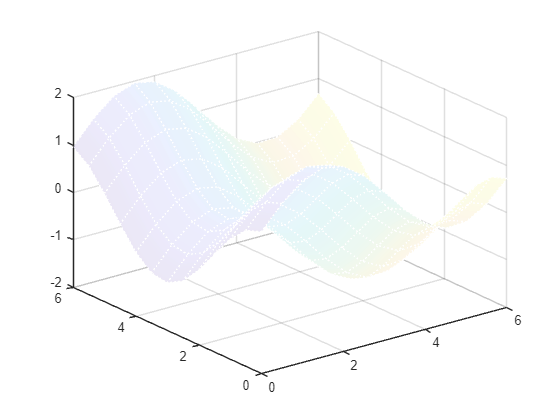

s.CData = X;
s.FaceAlpha = 0.1;